## **INSTANCE ANALYSIS**

This explores the instance set "instances_comb"; the original script to obtain the variables got lost, but fortunately we saved the workspace. So, we start by analyzing some of the variables obtained in the original version, and then we move forward to process new variable. 

**FIRST LETS ADD SOME FOLDERS**

addpath(genpath('../../../../extended/Domains/JSSP')); % Adds JSSP functionality
addpath(genpath('../../../../extended/Utils')); % Adds assorted utilities
addpath(genpath('../../../../Functionality')) %Adds HH and RHH functionality

**LOADING THE SAVED VARIABLES**

load("InstanceAnalysis.mat")

**PLOTTING THE MAKESPANS OBTAINED BY THE RANDOM MODELS FROM IS_EXP6 AND COMPARE THEM TO THE OPTIMAL MAKESPANS**

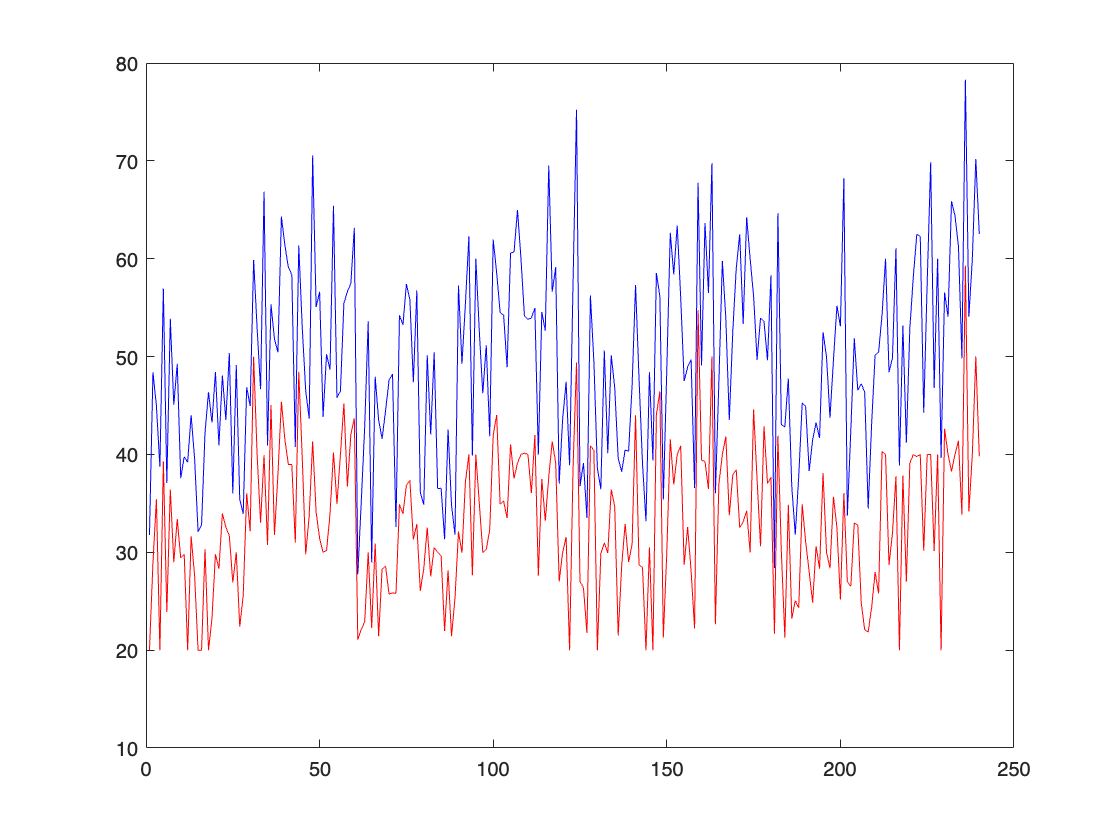

plot(instances_comb_optimal,'r')
hold on 
plot(SHH_means_means_means_byInstance, 'b') %results by mean

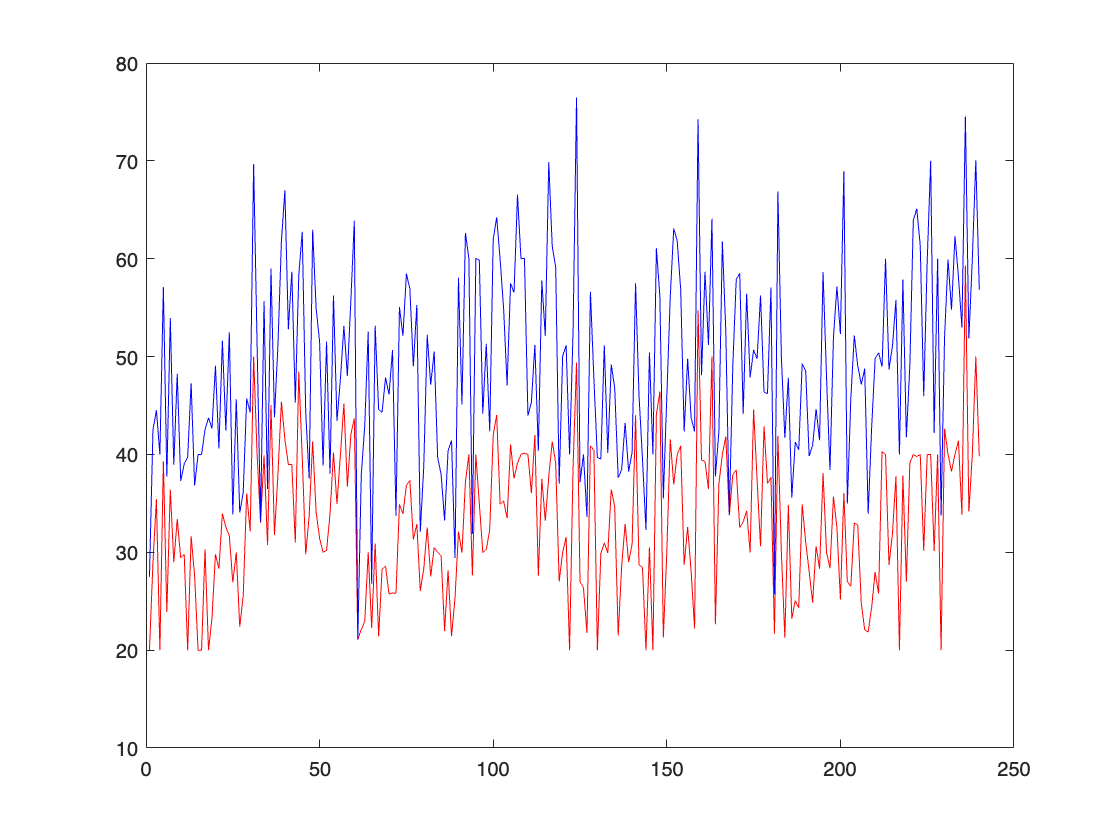

figure 
plot(instances_comb_optimal,'r')
hold on 
plot(CHH_means_means_means_byInstance, 'b')

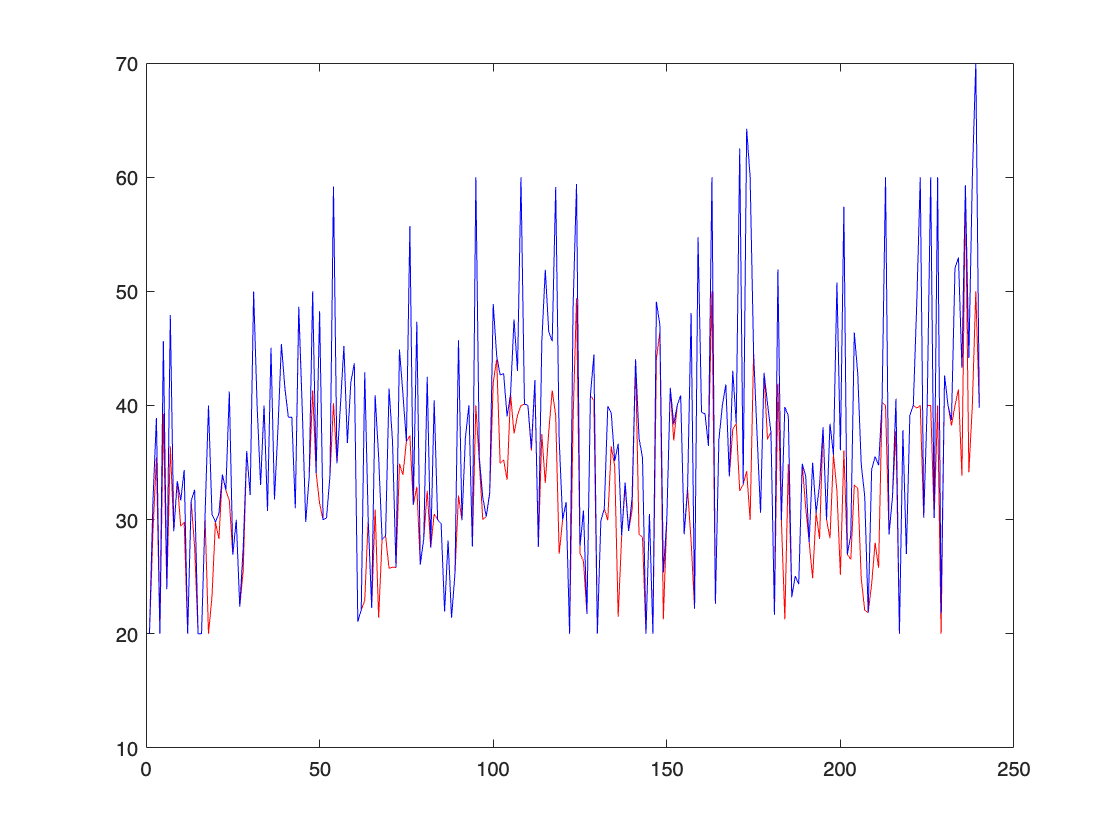

figure 
plot(instances_comb_optimal,'r')
hold on 
plot(SHH_mins_mins_mins_byInstance, 'b')

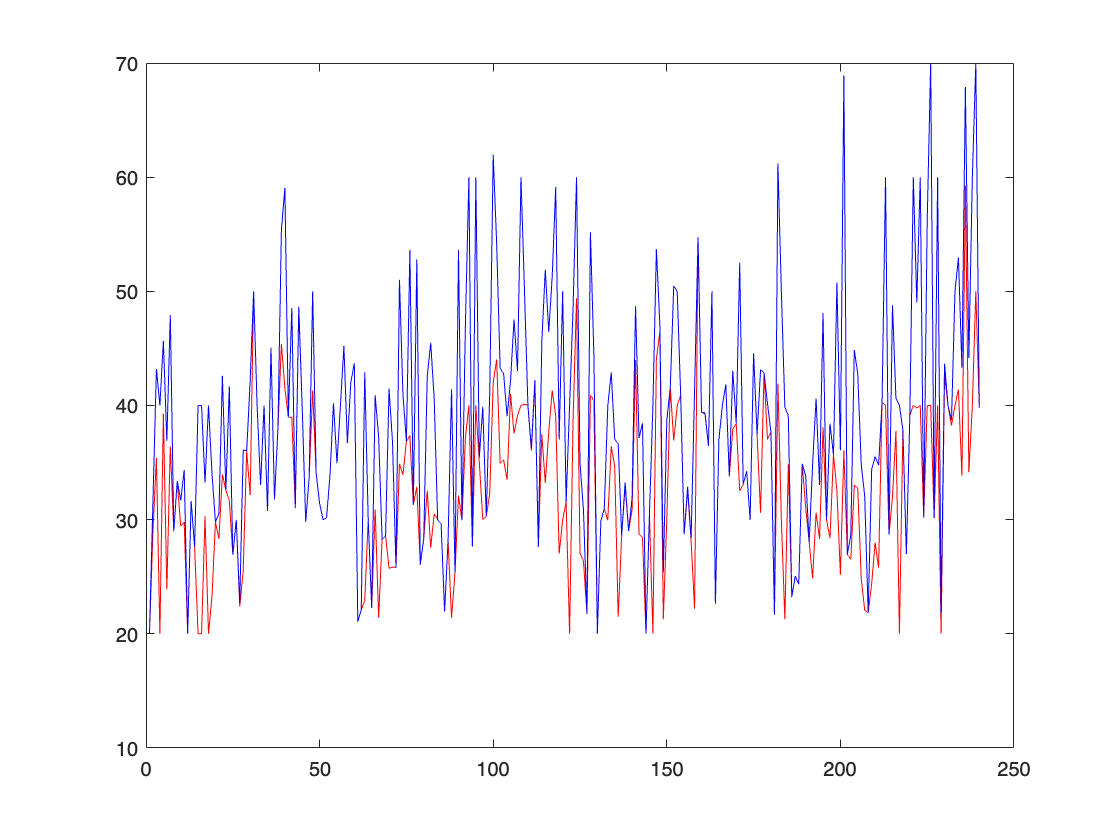

figure 
plot(instances_comb_optimal,'r')
hold on 
plot(CHH_mins_mins_mins_byInstance, 'b')

**THEN WE OBTAINED THE ROOT MEAN SQUARED ERROR BETWEEN THE RESULTS AND THE OPTIMALS**

SHH_means_RMSE

SHH_means_RMSE = 17.3590

CHH_means_RMSE

CHH_means_RMSE = 17.0411

SHH_mins_RMSE

SHH_mins_RMSE = 7.9186

CHH_mins_RMSE

CHH_mins_RMSE = 9.6554

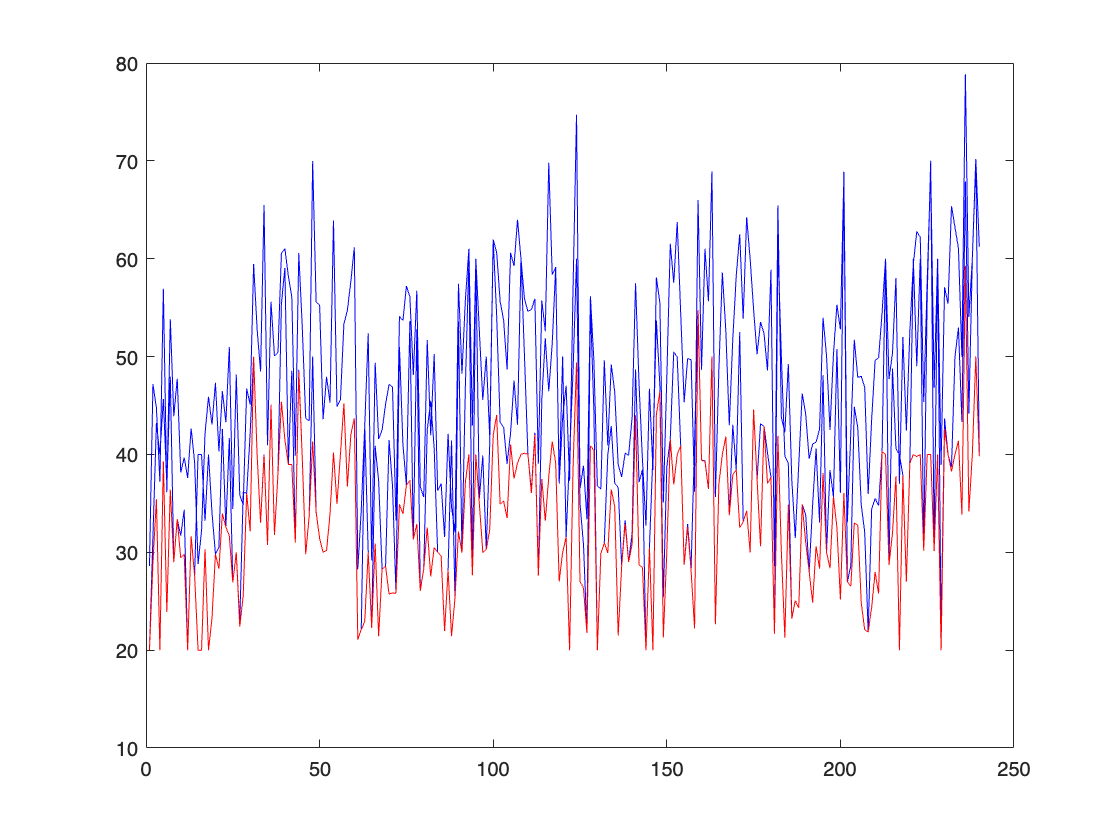

plot(instances_comb_optimal,'r')
hold on 
plot(mean(Replicas_100), 'b')

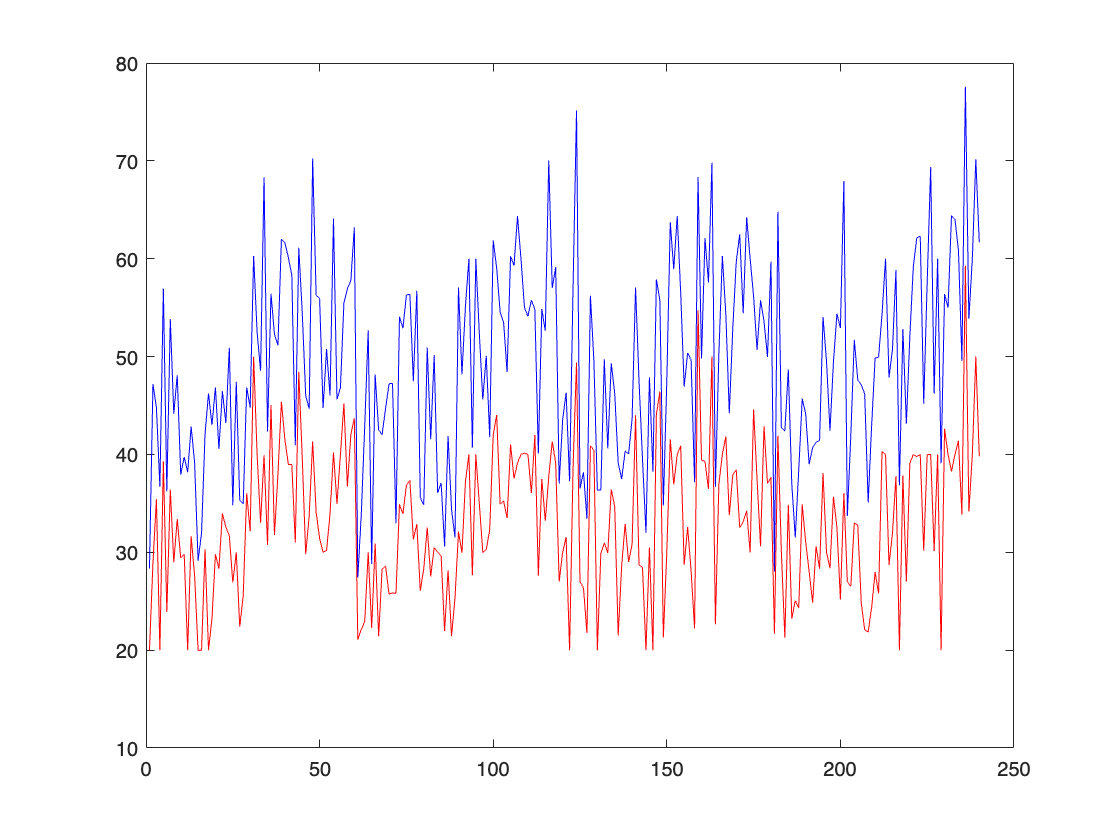

figure
plot(instances_comb_optimal,'r')
hold on 
plot(mean(Replicas_2000), 'b')

rmse(instances_comb_optimal,mean(Replicas_100))

ans = 17.0375

rmse(instances_comb_optimal,mean(Replicas_2000))

ans = 17.1898

**UNIQUE MAKESPANS**

%First let's obtain all the possible makespans of instances_comb 
%for doing so we need to run the BruteForceSolution code and save the
%allMakespans

instances_comb_unique=nan(1,length(instances_comb));

for x=1:length(instances_comb)
    var1=allMakespans(:,x); %saving all makespans of the instance x 
    instances_comb_unique(x)=length(unique(var1));
end 

instances_comb_unique

instances_comb_unique =      2    13    51     2    64     4    46    22    36     4     5     2    19    14     2     2     9     7    35    25    37     7    28    25    15     8     5     4     9     7    10     3    30    14     8    30    33    11     9    13    17    36    14    27    20     6    13    15     4    10


mean(instances_comb_unique)

ans = 19.6042



%Obtaining the different makespans from replicas100
replicas_100_unique=nan(1,length(instances_comb));
    
for x=1:length(instances_comb)
    var1=Replicas_100(:,x); %saving all makespans of the instance x 
    replicas_100_unique(x)=length(unique(var1));
end 

replicas_100_unique

replicas_100_unique =      2     8     4     2     7     4     3     6     8     3     2     2     6     3     2     2     4     2     8     5    11     4     5     4     7     5     4     3     6     4     5     3     5     3     2     7     4     3     4     2     3     6     4     9     6     2     4     3     3     3


mean(replicas_100_unique)

ans = 4.1375



%Obtaining the different makespans from replicas2000
replicas_2000_unique=nan(1,length(instances_comb));
    
for x=1:length(instances_comb)
    var1=Replicas_2000(:,x); %saving all makespans of the instance x 
    replicas_2000_unique(x)=length(unique(var1));
end 

replicas_2000_unique

replicas_2000_unique =      2     8     6     2    13     4     4    10    10     3     2     2     9     4     2     2     7     2    13     6    13     4     6     6     8     6     5     3     7     4     5     3     5     3     2     7     4     5     4     2     3     6     4    12     9     2     4     4     3     4


mean(replicas_2000_unique)

ans = 4.9375

**PLOTTING UNIQUE MAKESPANS **

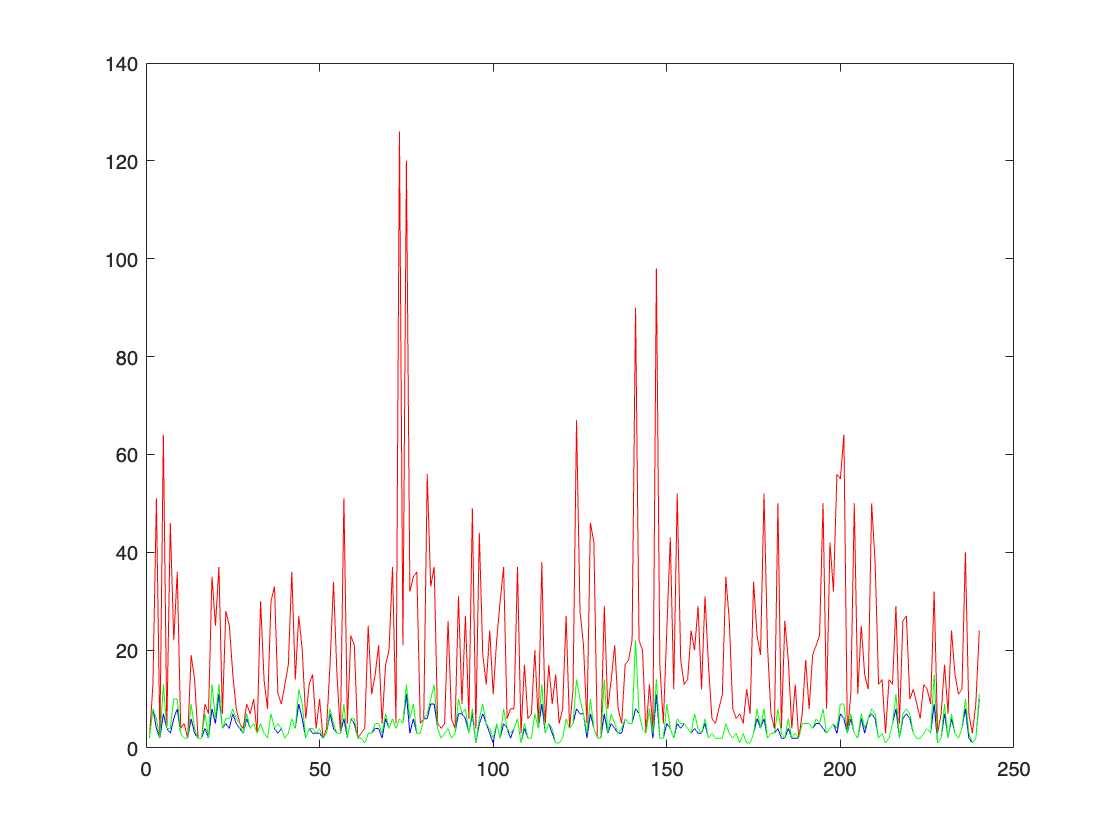

figure
plot(instances_comb_unique,'r')
hold on
plot(replicas_100_unique, 'b')
hold on 
plot(replicas_2000_unique,'g')

**Obtaining the unique makespans from the experiment of IS6**

randSHH_unique=nan(1,length(instances_comb));
    
for x=1:length(instances_comb)
    var1=solvedInstances_IS_Exp6_randSHH_comb_makespans(x,:,:,:); %saving all makespans of the instance x 
    randSHH_unique(x)=length(unique(var1));
end 

randSHH_unique

randSHH_unique =      2     8     6     2    21     4     4    10    11     3     3     2    10     7     2     2     7     2    16     6    15     4     8    11     8     6     5     3     7     4     5     3     5     3     2     7     5     5     4     2     4     6     4    12     9     2     4     6     3     4


mean(randSHH_unique)

ans = 5.5917



randCHH_unique=nan(1,length(instances_comb));
    
for x=1:length(instances_comb)
    var1=solvedInstances_IS_Exp6_randCHH_comb_makespans(x,:,:,:); %saving all makespans of the instance x 
    randCHH_unique(x)=length(unique(var1));
end 

randCHH_unique

randCHH_unique =      2     8     2     1    14     2     4     6    11     3     3     2    11     8     1     1     3     2     7     6    11     2     7     9    13     6     4     1     6     3     5     3     2     8     3     9     7     4     5     3     4     6     4    10     8     3     2     9     4     5


mean(randCHH_unique)

ans = 5.2625

**PLOTTING UNIQUE MAKESPANS **

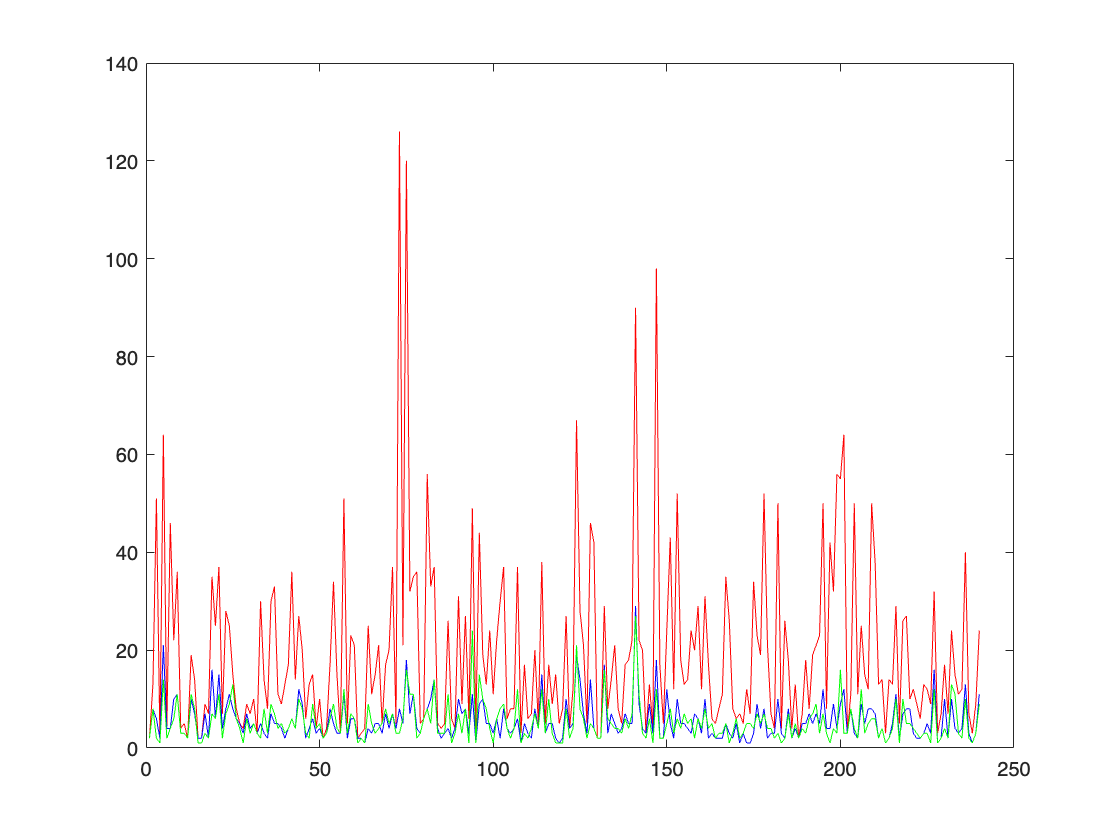

figure
plot(instances_comb_unique,'r')
hold on
plot(randSHH_unique, 'b')
hold on 
plot(randCHH_unique,'g')

save("InstanceAnalysis.mat")